%preguntar los nodos inicio y destino
inicio = input('Introduce el nodo de inicio: ');
final = input('Introduce el nodo final: ');
planif = input('Selecciona el modo de planificacion de caminos: Dijkstra(1) o A*(2): ');
%planificar camino
mapa2 %ejecutamos para obtener nodos y costes

if(planif == 2)
    %calculamos nueva heuristica
    n = size(nodos, 1);
    h = zeros(n, n);
    
    for i = 1:n
        for j = 1:n
            h(i,j) = norm(nodos(i, 2:3) - nodos(j, 2:3));
        end
    end
    %calculamos nueva matriz de costes
    costes_euclideos = zeros(size(costes));

    for i = 1:size(costes, 1)
        for j = 1:size(costes, 2)
            if costes(i,j) ~= 0 && i ~= j  % si hay conexión entre i y j
                costes_euclideos(i,j) = norm(nodos(i, 2:3) - nodos(j, 2:3));
            end
        end
    end
    costes = costes_euclideos;
    [coste_ruta, ruta]= aestrella(costes, h, inicio,final)
else
    [coste_ruta, ruta]= dijkstra(costes,inicio,final)
end

Nodos expandidos: 49


coste_ruta = 6

ruta =     37     3     7    43    45


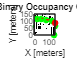


%esquivar obstáculos
map_img = imread('mapa2.pgm');
map_neg=imcomplement(map_img);
map_bin=imbinarize(map_neg);
mapa=binaryOccupancyMap(map_bin);
show(mapa);
origen=nodos(ruta(1), 2:3);
destino=nodos(ruta(2), 2:3);

%inicializaciones
% Configuracion del sensor (laser de barrido)
max_rango=10;
angulos=-pi/2:(pi/180):pi/2; % resolucion angular barrido laser
% Caracteristicas del vehiculo y parametros del metodo
v=0.4;            % Velocidad del robot
D=1.5;           % Rango del efecto del campo de repulsión de los obstáculos
alfa=1;           % Coeficiente de la componente de atracción
beta=100; 
iteracion = 0;
k = 0;
while k < numel(ruta) && iteracion < 1000
    hold on;
    plot(origen(1), origen(2), 'go','MarkerFaceColor','green');  % Dibujamos el origen
    plot(destino(1), destino(2), 'ro','MarkerFaceColor','red');  % Dibujamos el destino
    robot=[origen 0];     % El robot empieza en la posición de origen (orientacion cero)
    path = [];                 % Se almacena el camino recorrido
    path = [path; robot]; % Se añade al camino la posicion actual del robot
    iteracion=0;              % Se controla el nº de iteraciones por si se entra en un minimo local
    
    % Calculo de la trayectoria
    while norm(destino-robot(1:2)) > v && iteracion<1000    % Hasta menos de una iteración de la meta (10 cm)
    
        Fatr = alfa*(destino - robot(1:2));
        sum_Frep = [0, 0];
        array_obst = SimulaLidar(robot,mapa,angulos,max_rango);
    
        for a = 1:1:size(array_obst)
            obst = array_obst(a,:);
    
            if any(isnan(obst))
                continue
            end
    
            rho_obs = norm(robot(1:2) - obst);
            if rho_obs < D
                Frep = beta* ((1/rho_obs) - (1/D))*(robot(1:2)-obst)/(rho_obs^3);
            else 
                Frep = [0,0];
            end
            sum_Frep = sum_Frep + Frep;
        end
    
        Fres = Fatr + sum_Frep;
    
        if norm(Fres) > 0
            direction = Fres / norm(Fres);
        end
        theta = atan2(direction(2), direction(1));
        robot = [robot(1) + v*direction(1), robot(2) + v*direction(2), theta];
    
        path = [path;robot];	% Se añade la nueva posición al camino seguido
        plot(path(:,1),path(:,2),'r');
        drawnow
    
        iteracion=iteracion+1;
    end
    
    if iteracion==1000   % Se ha caído en un mínimo local
        fprintf('No se ha podido llegar al destino.\n')
    elseif destino == final
        fprintf('Destino alcanzado.\n')
    end

    %actualizamos siguiente posicion destino y origen
    k = k + 1;
    origen=nodos(ruta(k), 2:3);
    if k < numel(ruta)
        destino=nodos(ruta(k+1), 2:3);
    end
end

function [obs]=SimulaLidar(robot, mapa, angulos, max_rango)
    obs=rayIntersection(mapa,robot,angulos, max_rango);
    % plot(obs(:,1),obs(:,2),'*r') % Puntos de interseccion lidar
    % plot(robot(1),robot(2),'ob') % Posicion del robot
    % for i = 1:length(angulos)
    %     plot([robot(1),obs(i,1)],...
    %         [robot(2),obs(i,2)],'-b') % Rayos de interseccion
    % end
    % % plot([robot(1),robot(1)-6*sin(angulos(4))],...
    % %     [robot(2),robot(2)+6*cos(angulos(4))],'-b') % Rayos fuera de
    % %     rango
end